# Displaying Multiple Plots in a Single Figure

This example shows how to display multiple plots in a single figure in MATLAB® by using `subplot`.

## Create Subplots Using Grid Positions

You can create a figure containing multiple plots using the `subplot` function. The `subplot` function takes three inputs. The first two inputs, `m` and `n`, divide the current figure into an *m* by *n* grid. The third input specifies the position in the grid where the new axes are created. The grid position specified by the third input is a row-based index.

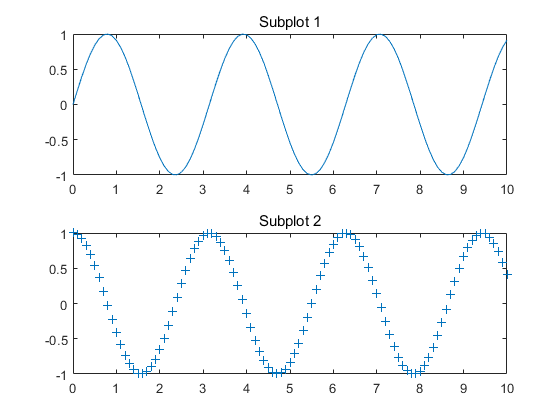

x = 0:0.1:10;
y1 = sin(2*x);
y2 = cos(2*x);

figure
subplot(2,1,1)       % add first plot in 2 x 1 grid
plot(x,y1)
title('Subplot 1')

subplot(2,1,2)       % add second plot in 2 x 1 grid
plot(x,y2,'+')       % plot using + markers
title('Subplot 2')

Subplots in a figure can contain any type of MATLAB plot.

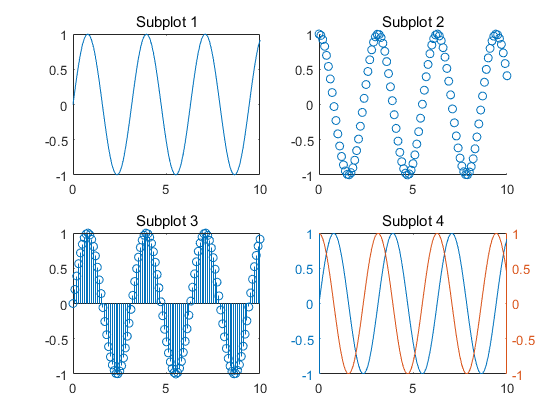

figure
subplot(2,2,1)       % add first plot in 2 x 2 grid
plot(x,y1)           % line plot
title('Subplot 1')

subplot(2,2,2)       % add second plot in 2 x 2 grid
scatter(x,y2)        % scatter plot
title('Subplot 2')

subplot(2,2,3)       % add third plot in 2 x 2 grid
stem(x,y1)           % stem plot
title('Subplot 3')

subplot(2,2,4)       % add fourth plot in 2 x 2 grid
yyaxis left          % plot against left y-axis  
plot(x,y1)           
yyaxis right         % plot against right y-axis
plot(x,y2)
title('Subplot 4')

## Create a Subplot that Spans Multiple Grid Positions

A subplot can span multiple subplot positions. To do this, specify the third argument as an array of positions.

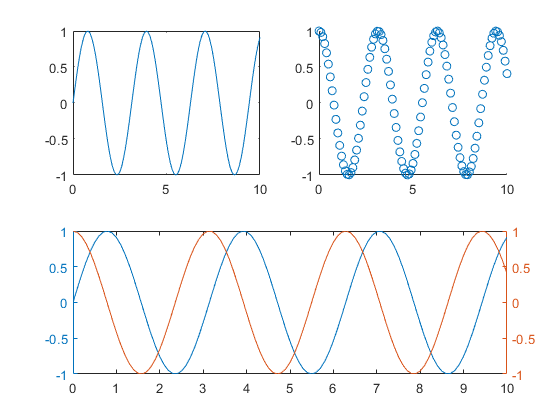

figure
subplot(2,2,1)        % add first plot in 2 x 2 grid
plot(x,y1)            % line plot

subplot(2,2,2)        % add second plot in 2 x 2 grid
scatter(x,y2)         % scatter plot

subplot(2,2,[3 4])    % add third plot to span positions 3 and 4
yyaxis left           % plot against left y-axis 
plot(x,y1)           
yyaxis right          % plot against right y-axis
plot(x,y2)

## Create Subplots Using Axes Positions

You also can set the subplot position in a figure by specifying the axes position as an optional input to the `subplot` function. The position is a four-element vector (`[left,bottom,width,height]`) where each value is between 0 and 1. By default, `subplot` keeps the inner axes of your plots aligned. Inner axes are not automatically aligned when the position is set explicitly.

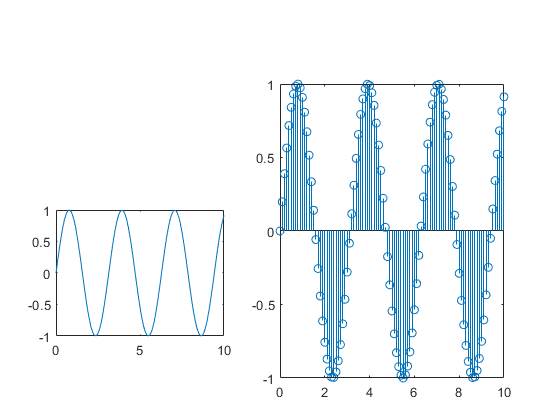

positionVector1 = [0.1, 0.2, 0.3, 0.3];    % position of first subplot
figure
subplot('Position',positionVector1)
plot(x,y1)

positionVector2 = [0.5, 0.1, 0.4, 0.7];    % position of second subplot
subplot('Position',positionVector2)
stem(x,y1)

## Change Subplot Properties

The output of the `subplot` function is the axes object corresponding to that subplot. To customize the look of any subplot, change its property values using the dot notation syntax `object.PropertyName`

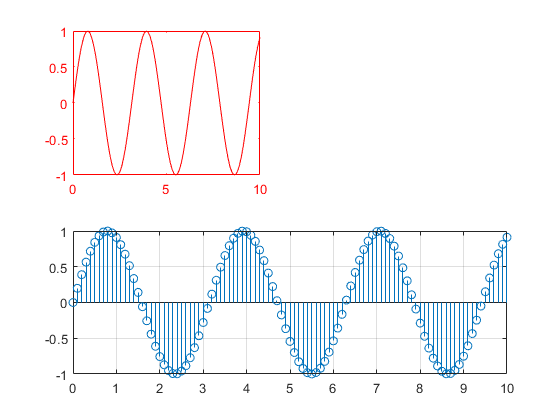

figure
ax1 = subplot(2,2,1);        % add first plot in 2 x 1 grid
plot(x,y1,'r')               % plot line in red
ax1.XColor = 'red';          % set x axes color to red
ax1.YColor = 'red';          % set y axes color to red

ax2 = subplot(2,2,[3 4]);    % add second plot in 2 x 1 grid
stem(x,y1)                   % stem plot
ax2.XGrid = 'on';            % display x grid
ax2.YGrid = 'on';            % display y grid